clear all
addpath("functions/");


if ismac
  addpath("coppelia_files/mac")
elseif isunix
  addpath("coppelia_files/linux")
end

disp('Program started');

Program started


% sim=remApi('remoteApi','extApi.h'); % using the header (requires a compiler)
sim=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1); % just in case, close all opened connections
clientID=sim.simxStart('127.0.0.1',19997,true,true,5000,5);

if (clientID>-1)
    disp('Connected to remote API server');
    [returnCode]=sim.simxLoadScene(clientID,'scenes/3-dof.ttt',1,sim.simx_opmode_blocking)
    display(returnCode);
    
    % Now send some data to CoppeliaSim in a non-blocking fashion:
    sim.simxAddStatusbarMessage(clientID,'Hello CoppeliaSim!',sim.simx_opmode_oneshot);
    
    [returnCode,joint1] = sim.simxGetObjectHandle(clientID,'Joint1', sim.simx_opmode_blocking)
    [returnCode,joint2] = sim.simxGetObjectHandle(clientID,'Joint2', sim.simx_opmode_blocking)
    [returnCode,joint3] = sim.simxGetObjectHandle(clientID,'Joint3', sim.simx_opmode_blocking)
    
    joints = [joint1,joint2,joint3]
    
    %load Franka
    %[returnCode, baseHandle] = sim.simxLoadModel(clientID, 'models/robots/non-mobile/FrankaEmikaPanda.ttm', 0,sim.simx_opmode_blocking);
    %sim.simxAddStatusbarMessage(clientID,'Model loaded',sim.simx_opmode_oneshot);
    %display(returnCode);
    %display(baseHandle);
    
else
    disp('Failed connecting to remote API server');
end

Connected to remote API server


returnCode = 0

returnCode = 0

returnCode = 0

joint1 = int32
17

returnCode = 0

joint2 = int32
19

returnCode = 0

joint3 = int32
21

joints = 1×3 int32 row vector
   17   19   21


[position1, velocity1, acceleration1, time1] = load_trajectory('data/3-dof/trajectory1');
[position2, velocity2, acceleration2, time2] = load_trajectory('data/3-dof/trajectory2');
[position3, velocity3, acceleration3, time3] = load_trajectory('data/3-dof/trajectory3');

time_tmp = [time1; time2; time3];
position_tmp = [position1; position2; position3];
velocity_tmp = [velocity1; velocity2; velocity3];
acceleration_tmp = [acceleration1; acceleration2; acceleration3];

% [x1, y1, z1] = looping_splines(position_tmp(1,:), time_tmp(1,:));
% [x2, y2, z2] = looping_splines(position_tmp(2,:), time_tmp(2,:));
% [x3, y3, z3] = looping_splines(position_tmp(3,:), time_tmp(3,:));

[x1, y1, z1] = looping_splines([0 pi 0 pi 0],[0 5 10 15 20]);
[x2, y2, z2] = looping_splines([-pi/2 -pi/4 -pi/2],[0 10 20]);
[x3, y3, z3] = looping_splines([0 pi/4 -pi/3 0],[0 5 15 20]);

% period = double(lcm(sym([time_tmp(1, size(time_tmp, 2)), time_tmp(2, size(time_tmp, 2)), time_tmp(3, size(time_tmp, 2))])));
period = 20;

position = {x1, x2, x3}

position = 1×3 cell array
    {@(x)tmp_pos(mod(x,times(len)))}    {@(x)tmp_pos(mod(x,times(len)))}    {@(x)tmp_pos(mod(x,times(len)))}


velocity = {y1, y2, y3}

velocity = 1×3 cell array
    {@(x)tmp_vel(mod(x,times(len)))}    {@(x)tmp_vel(mod(x,times(len)))}    {@(x)tmp_vel(mod(x,times(len)))}


acceleration = {z1, z2, z3}

acceleration = 1×3 cell array
    {@(x)tmp_acc(mod(x,times(len)))}    {@(x)tmp_acc(mod(x,times(len)))}    {@(x)tmp_acc(mod(x,times(len)))}


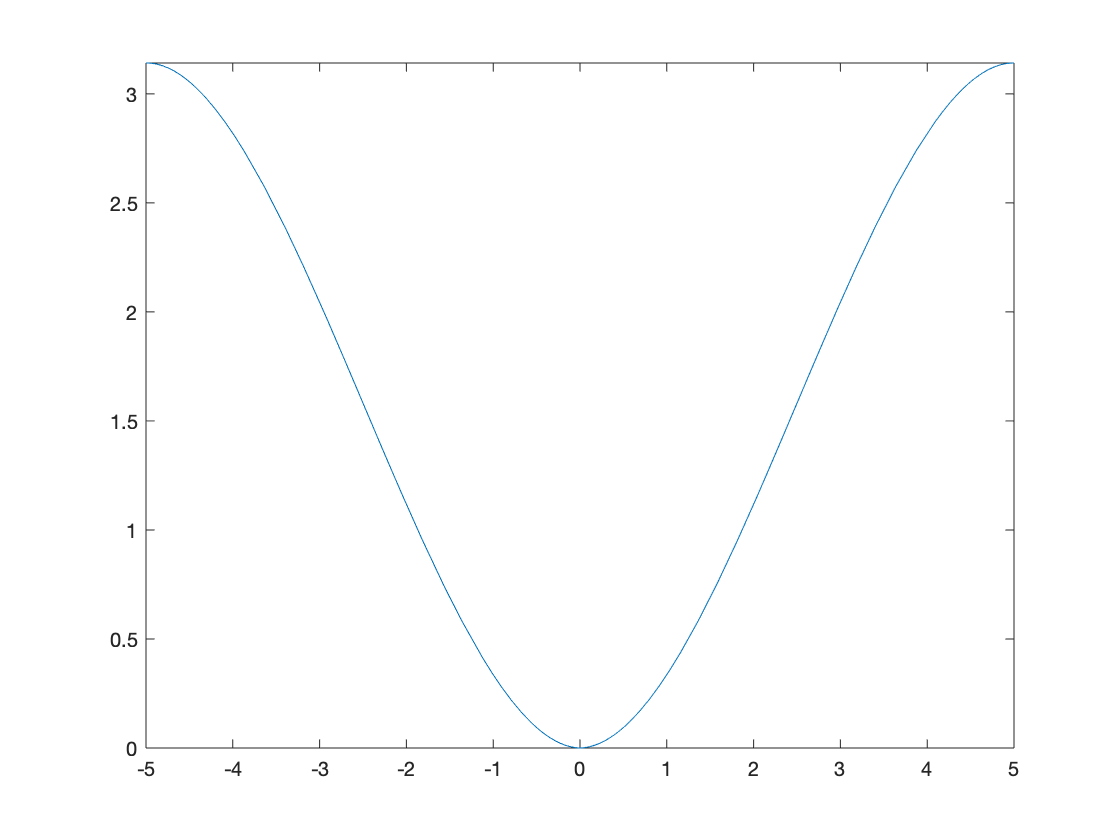

fplot(position(1))

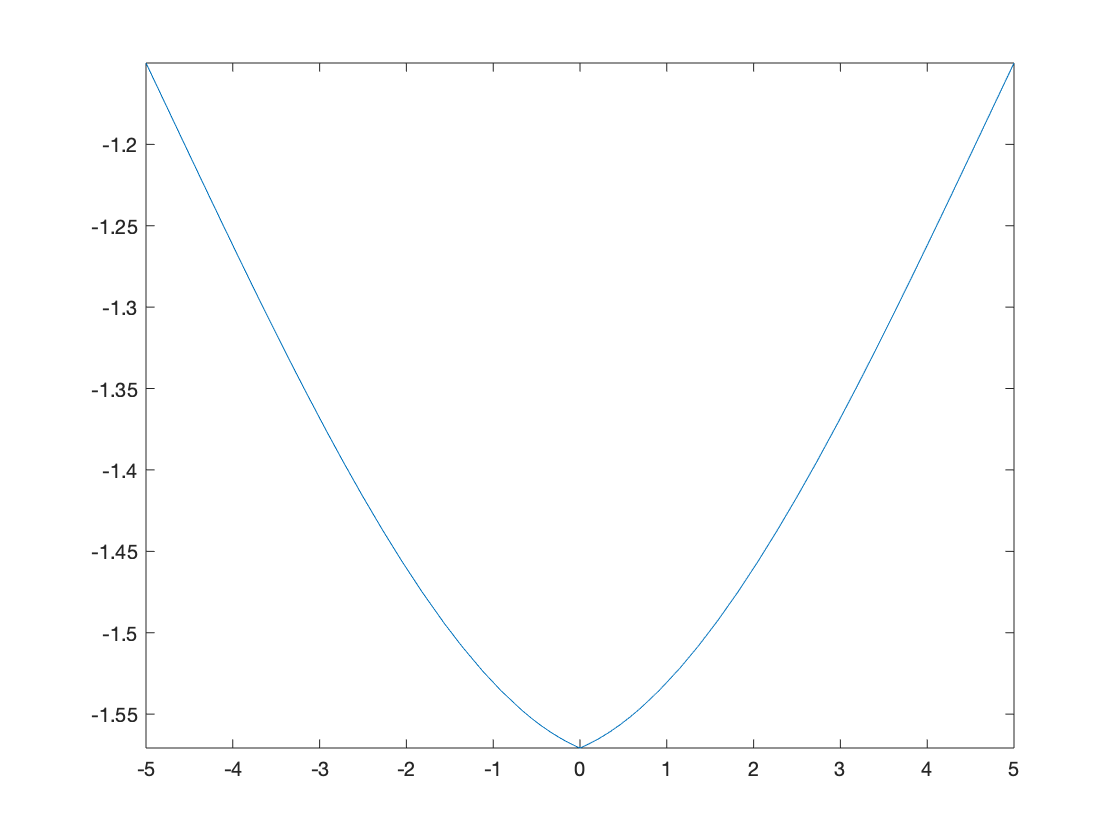

fplot(position(2))

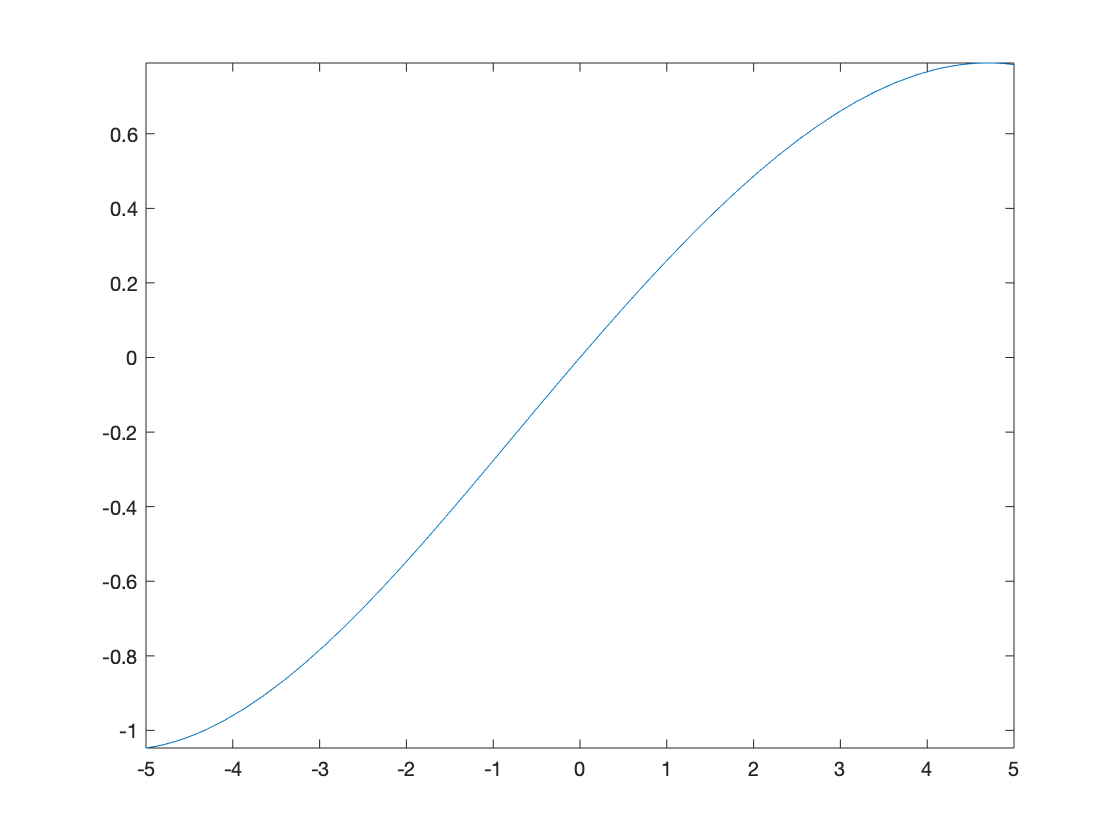

fplot(position(3))

sim.simxStartSimulation(clientID, sim.simx_opmode_oneshot);

sim.simxSetJointPosition(clientID,joints(1),0,sim.simx_opmode_oneshot);
sim.simxSetJointPosition(clientID,joints(2),-pi/2,sim.simx_opmode_oneshot);
sim.simxSetJointPosition(clientID,joints(3),0,sim.simx_opmode_oneshot);
sim.simxGetPingTime(clientID);

[returnCode,joint_position1]=sim.simxGetJointPosition(clientID,joint1,sim.simx_opmode_streaming)

returnCode = 1

joint_position1 = single
43

[returnCode,joint_position2]=sim.simxGetJointPosition(clientID,joint2,sim.simx_opmode_streaming)

returnCode = 1

joint_position2 = single
43

[returnCode,joint_position3]=sim.simxGetJointPosition(clientID,joint3,sim.simx_opmode_streaming)

returnCode = 1

joint_position3 = single
43

controller_gain =0.005

controller_gain = 0.0050

controller_gain = [1; 0.4; 0.03] %

controller_gain =     1.0000
    0.4000
    0.0300


Kp_orig = [2.5; 4; 3].*controller_gain;
Kd_orig = [2; 4; 3].*controller_gain;
Ki_orig = [2; 3; 1].*controller_gain;

% Repeat the whole experiment multiple times
[vk1, dvk1, ddvk1] = looping_splines([0 0], [0 1]);
[vk2, dvk2, ddvk2] = looping_splines([0 0], [0 1]);
[vk3, dvk3, ddvk3] = looping_splines([0 0], [0 1]);

vk = {vk1, vk2, vk3};

for rep=1:1
    sim.simxStartSimulation(clientID, sim.simx_opmode_oneshot);
    
    measured_pos = zeros(3, 500000);
    reference_pos = zeros(3, 500000);
    measured_vel = zeros(3, 500000);
    reference_vel = zeros(3, 500000);
    time_axis = zeros(1, 500000);
    error = zeros(3, 500000);
    derror = zeros(3, 500000);
    ierror = zeros(3, 500000);
    torque = zeros(3, 500000);
    computed = zeros(3, 500000);
    correction = zeros(3, 500000);
    i = 1;

    queue = [0 0; 0 0; 0 0];
    
    decay = 1; %0.1 + 0.9*exp(-0.5*rep);
    Kp = decay * Kp_orig;
    Kd = decay * Kd_orig;
    Ki = decay * Ki_orig;

    t0 = datetime('now');
    t1 = t0;
    start = t0;
    integral = [0; 0; 0];
    u = [0; 0; 0];

    while seconds(t1-start)<=period*3
        t1 = datetime('now');
        frame_period = (seconds(t1-start)/i);
        frame_rate = 1/frame_period;
        
        [returnCode,joint_position1]=sim.simxGetJointPosition(clientID,joints(1),sim.simx_opmode_buffer);
        [returnCode,joint_position2]=sim.simxGetJointPosition(clientID,joints(2),sim.simx_opmode_buffer);
        [returnCode,joint_position3]=sim.simxGetJointPosition(clientID,joints(3),sim.simx_opmode_buffer);
        
        q = [joint_position1; joint_position2; joint_position3];
        
        queue(:,2) = queue(:,1);
        queue(:,1) = q;
        
        v = (queue(:,1)-queue(:,2))/seconds(t1-t0);
        measured_vel(:, i) = v;
        
        qd1 = position{1}(seconds(t1-start));
        qd2 = position{2}(seconds(t1-start));
        qd3 = position{3}(seconds(t1-start));
        qd = [qd1; qd2; qd3];
        integral = integral + (qd - q)*seconds(t1-t0);
        integral = [0; 0; 0];
    
        dqd1 = velocity{1}(seconds(t1-start));
        dqd2 = velocity{2}(seconds(t1-start));
        dqd3 = velocity{3}(seconds(t1-start));
        dqd = [dqd1; dqd2; dqd3];
        ui = Kp.*(qd - q) + Kd.*(dqd - v) + Ki.*integral;
        
        ff1 = vk{1}(seconds(t1-start));
        ff2 = vk{2}(seconds(t1-start));
        ff3 = vk{3}(seconds(t1-start));
        ff = [ff1; ff2; ff3];

        % estimated gravity compensation
        g = [0; 
            9.81*0.9511*(0.3*cos(q(2))+0.1050*cos(q(2)+q(3))) + 9.81*0.1873*8.0853*cos(q(2));
            9.81*0.1050*0.9511*cos(q(2)+q(3))];

%       exact gravity
%         g = [0; 
%             9.81*((0.1*cos(q(2) + q(3))) + 0.3*cos(q(2))) + (0.15*9.81*10*cos(q(2)));
%             (0.1*9.81*1*cos(q(2) + q(3)))];
%         
        if (rep==1)
            ff=g;
        end
        
        u = ui + ff;
        torque(:, i) = double(u);
        computed(:, i) = ff;
        correction(:, i) = ui;
        
        time_axis(1, i) = seconds(t1-start);
        
        measured_pos(:, i) = q;
        reference_pos(:, i) = qd;
        
        reference_vel(:, i) = dqd;
        
        error(:, i) = qd - q;
        derror(:, i) = dqd - v;
        ierror(:, i) = integral;

        % Send torque to robot
        sim.simxPauseCommunication(clientID,1);
        for j=1:3
            sim.simxSetJointTargetVelocity(clientID, joints(j), sign(u(j))*10e10, sim.simx_opmode_oneshot);
            sim.simxSetJointForce(clientID, joints(j), abs(u(j)), sim.simx_opmode_oneshot);
        end
        sim.simxPauseCommunication(clientID,0);
        
        i = i+1;
        t0=t1;
        
        pause(0.02)
    end
    
    sim.simxStopSimulation(clientID, sim.simx_opmode_oneshot);
    
    ORDER = 16;
    FC_HIGH = frame_rate/16;  % Hz, used in low-pass and band-pass filters

    filt = designfilt('lowpassiir', 'FilterOrder', ORDER, 'HalfPowerFrequency', FC_HIGH, 'SampleRate', frame_rate);
    
    [vk1, dvk1, ddvk1] = looping_splines(filtfilt(filt, torque(1, 1:i-1)), time_axis(1, 1:i-1));
    [vk2, dvk2, ddvk2] = looping_splines(filtfilt(filt, torque(2, 1:i-1)), time_axis(1, 1:i-1));
    [vk3, dvk3, ddvk3] = looping_splines(filtfilt(filt, torque(3, 1:i-1)), time_axis(1, 1:i-1));
    
%     [alphaui1, dvk1, ddvk1] = looping_splines(filtfilt(filt, correction(1, 1:i-1)), time_axis(1, 1:i-1));
%     [alphaui2, dvk2, ddvk2] = looping_splines(filtfilt(filt, correction(2, 1:i-1)), time_axis(1, 1:i-1));
%     [alphaui3, dvk3, ddvk3] = looping_splines(filtfilt(filt, correction(3, 1:i-1)), time_axis(1, 1:i-1));
%     
%     [betavk1, dvk1, ddvk1] = looping_splines(filtfilt(filt, computed(1, 1:i-1)), time_axis(1, 1:i-1));
%     [betavk2, dvk2, ddvk2] = looping_splines(filtfilt(filt, computed(2, 1:i-1)), time_axis(1, 1:i-1));
%     [betavk3, dvk3, ddvk3] = looping_splines(filtfilt(filt, computed(3, 1:i-1)), time_axis(1, 1:i-1));
%     
%     vk1 = @(t) alphaui1(t) + betavk1(t);
%     vk2 = @(t) alphaui2(t) + betavk2(t);
%     vk3 = @(t) alphaui3(t) + betavk3(t);
    
    vk = {vk1, vk2, vk3};
    
end

frame_rate

frame_rate = 37.8744

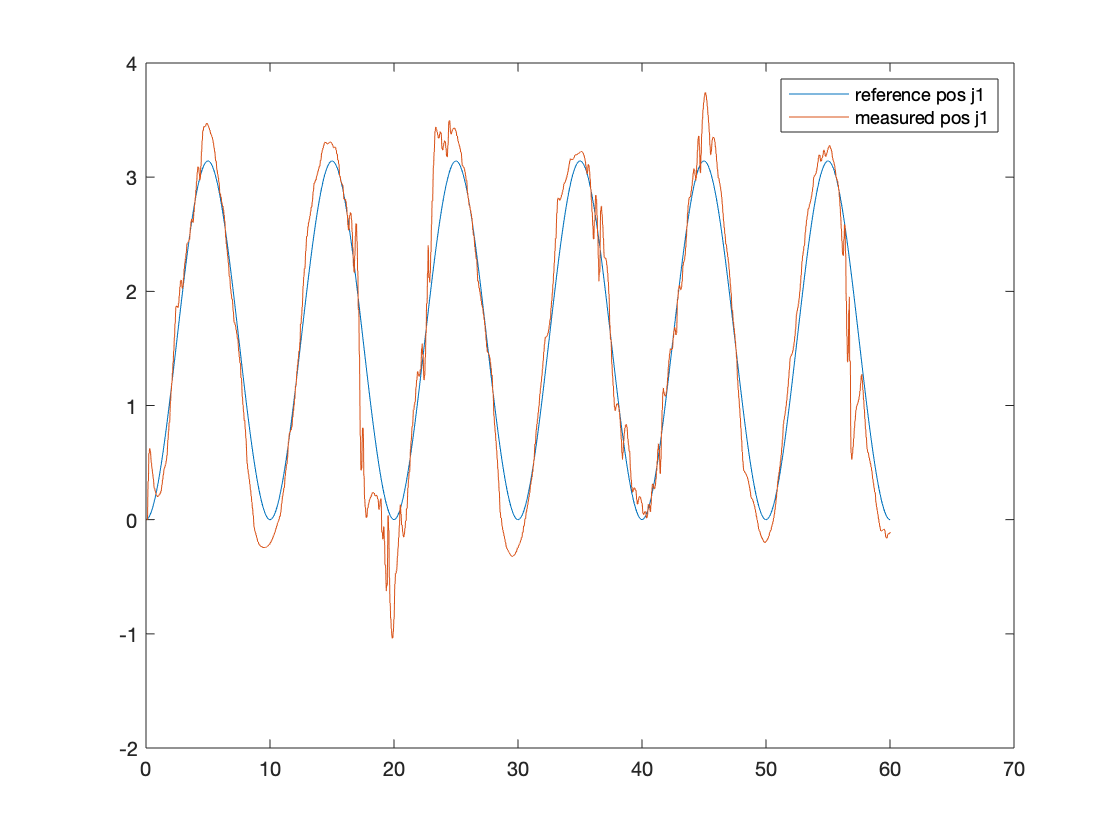

clf
plot(time_axis(1, 1:i-1), reference_pos(1, 1:i-1), time_axis(1, 1:i-1), measured_pos(1, 1:i-1));
legend ("reference pos j1", "measured pos j1")

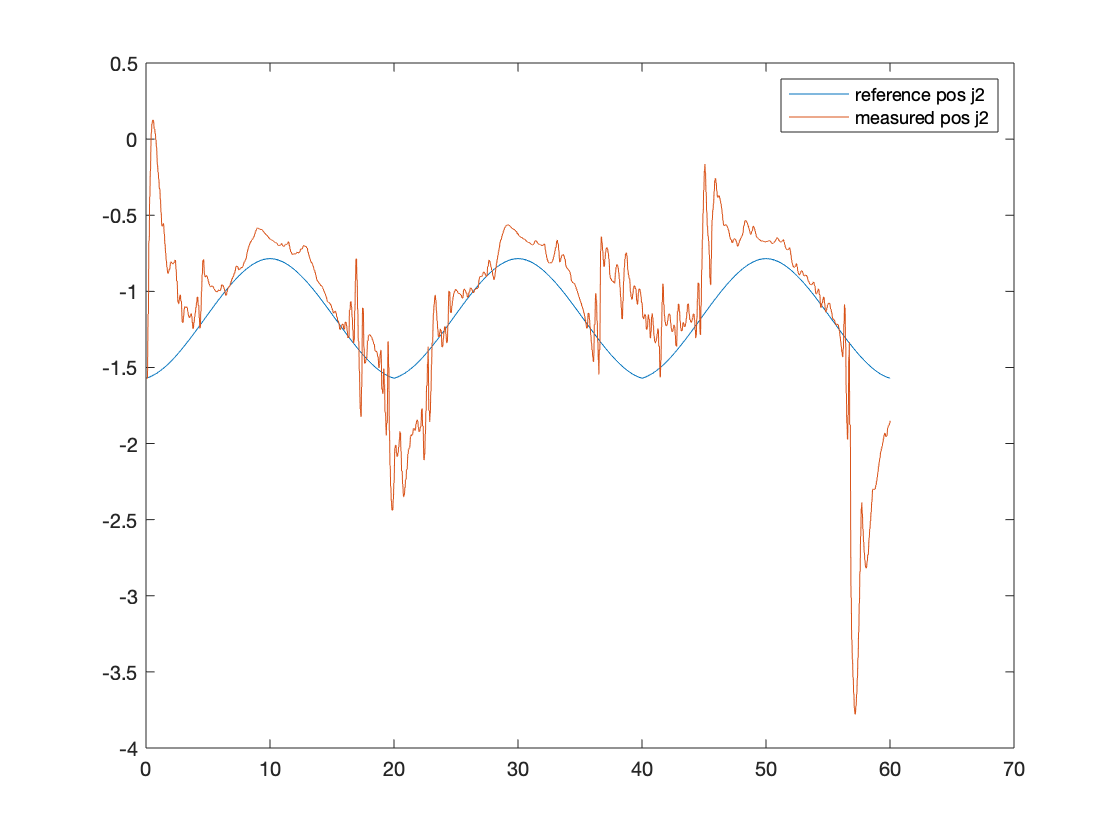

clf
plot(time_axis(1, 1:i-1), reference_pos(2, 1:i-1), time_axis(1, 1:i-1), measured_pos(2, 1:i-1));
legend ("reference pos j2", "measured pos j2")

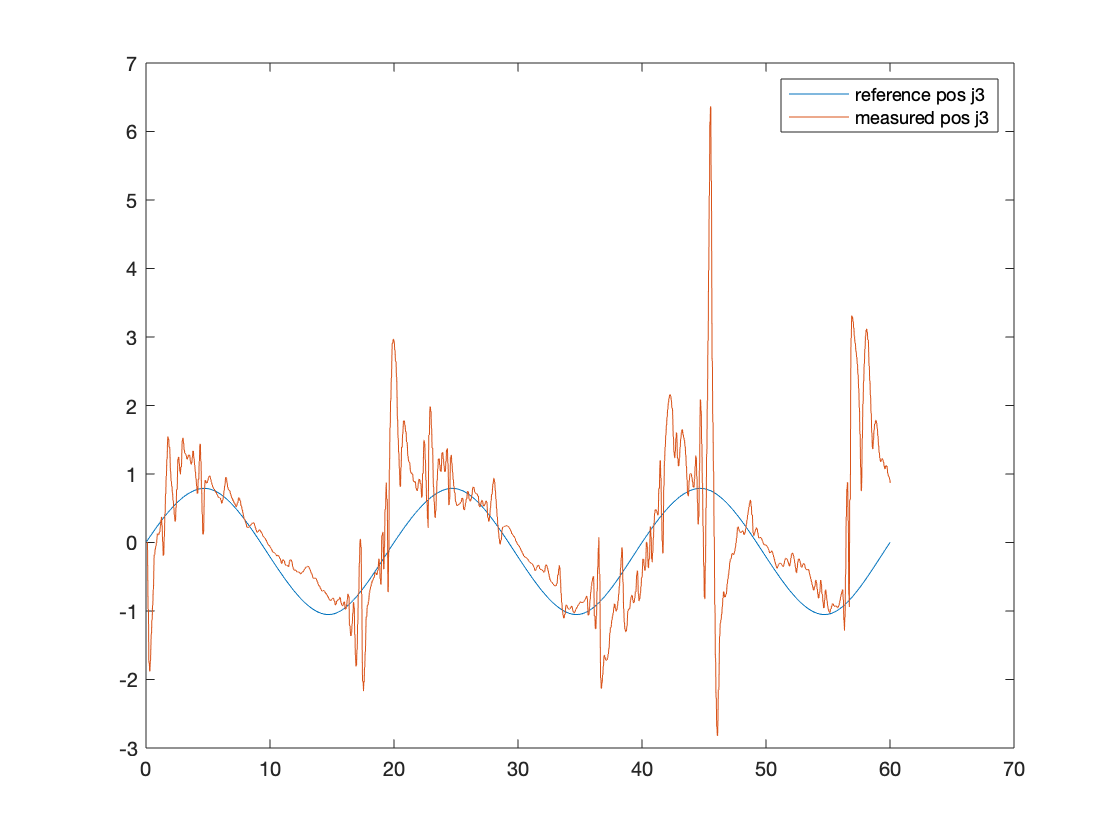

clf
plot(time_axis(1, 1:i-1), reference_pos(3, 1:i-1), time_axis(1, 1:i-1), measured_pos(3, 1:i-1));
legend ("reference pos j3", "measured pos j3")

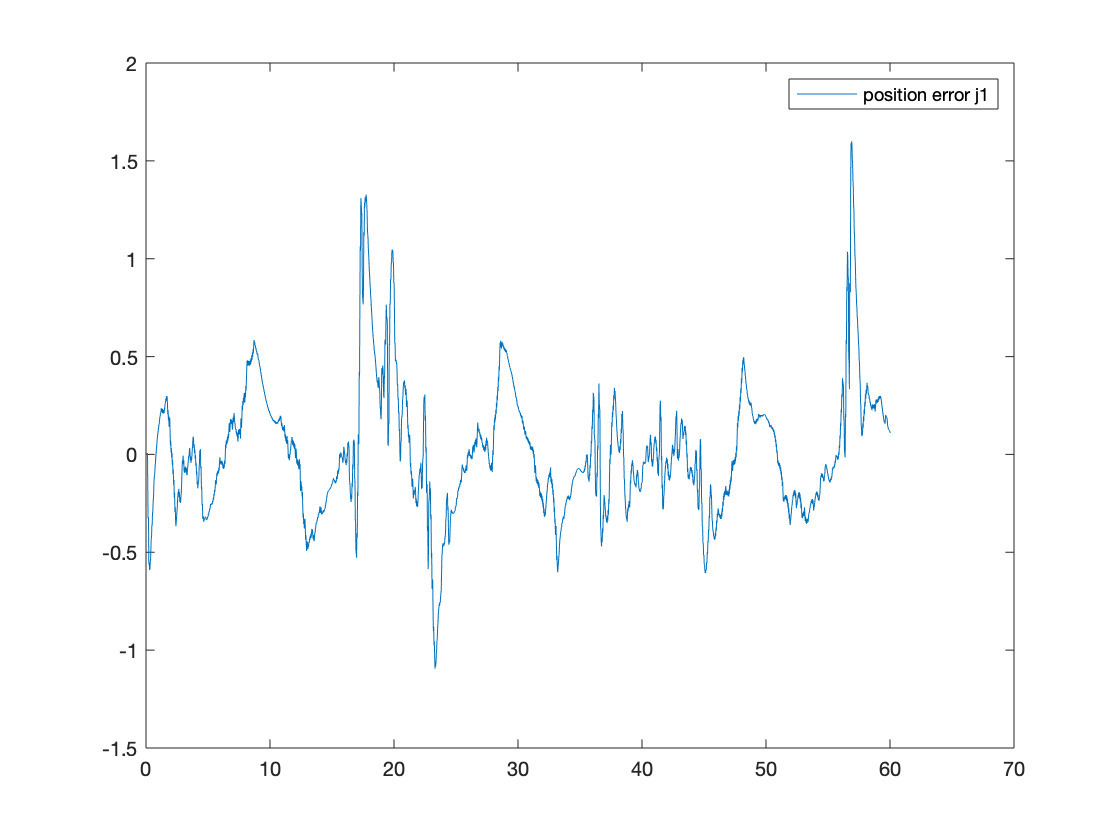

clf
plot(time_axis(1, 1:i-1), error(1, 1:i-1));
legend("position error j1")

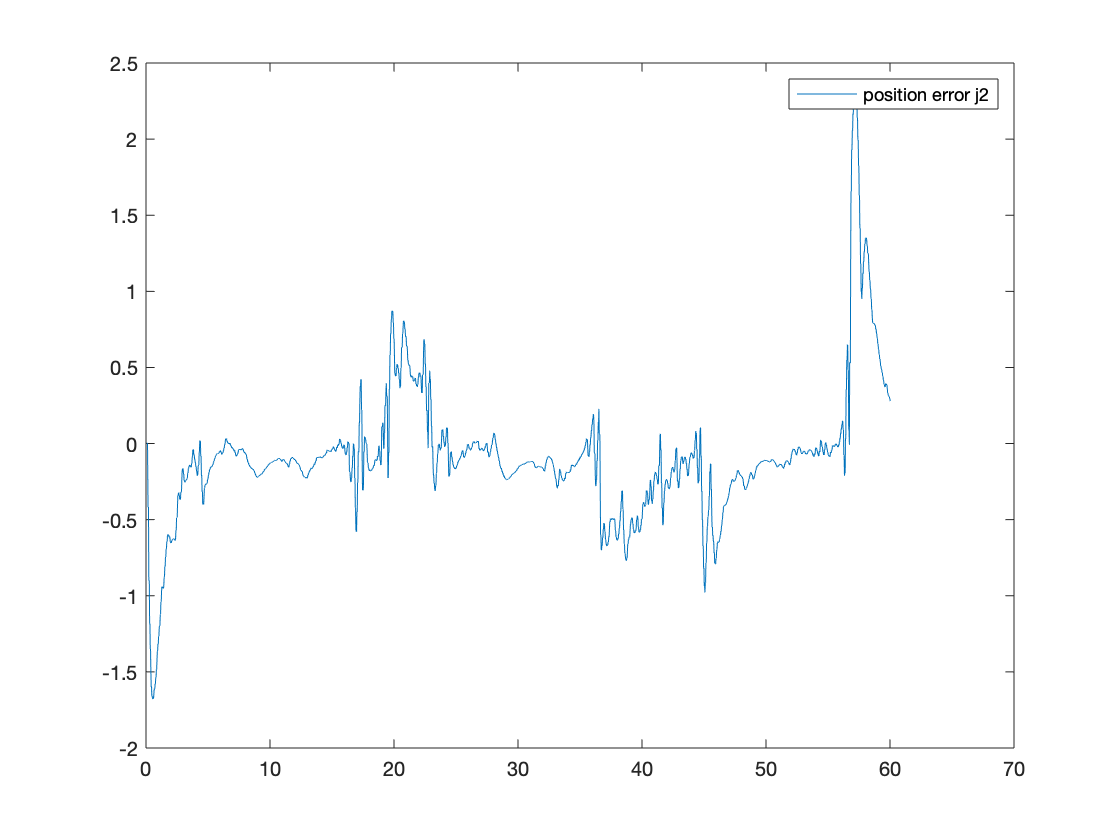

clf
plot(time_axis(1, 1:i-1), error(2, 1:i-1));
legend("position error j2")

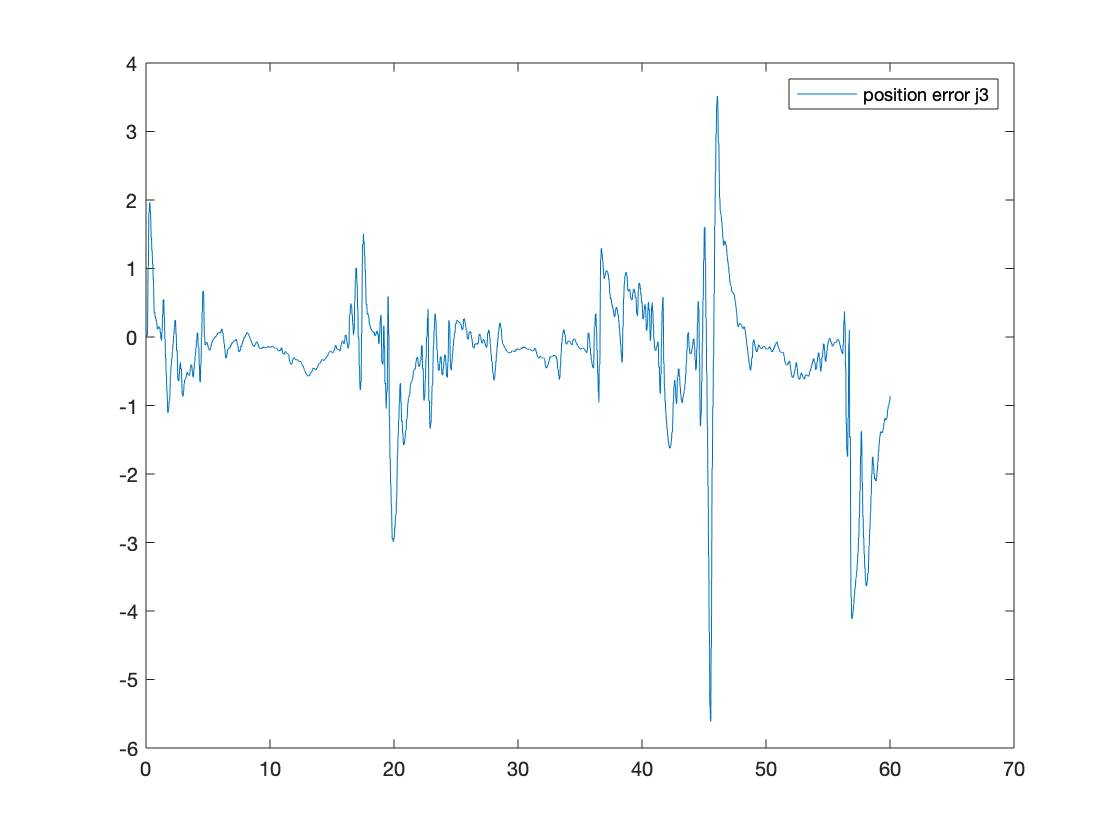

clf
plot(time_axis(1, 1:i-1), error(3, 1:i-1));
legend("position error j3")

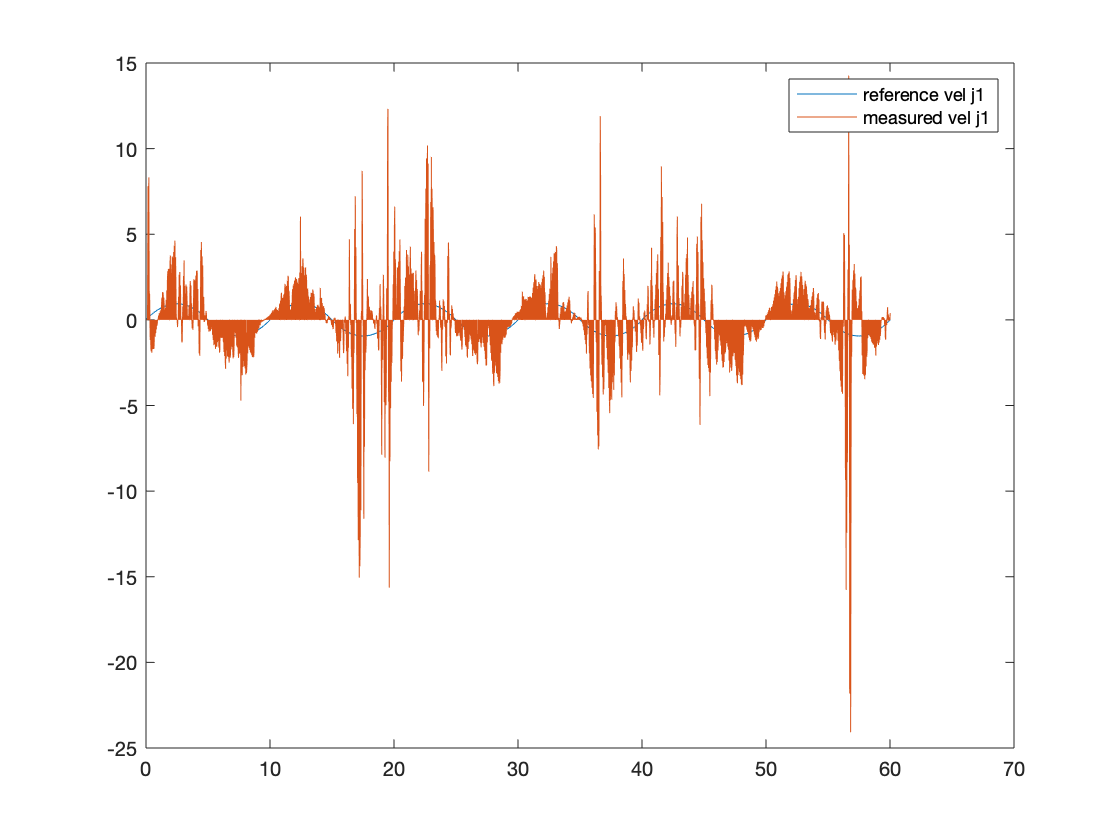

clf;
plot(time_axis(1, 1:i-1), reference_vel(1, 1:i-1), time_axis(1, 1:i-1), measured_vel(1, 1:i-1));
legend ("reference vel j1", "measured vel j1")

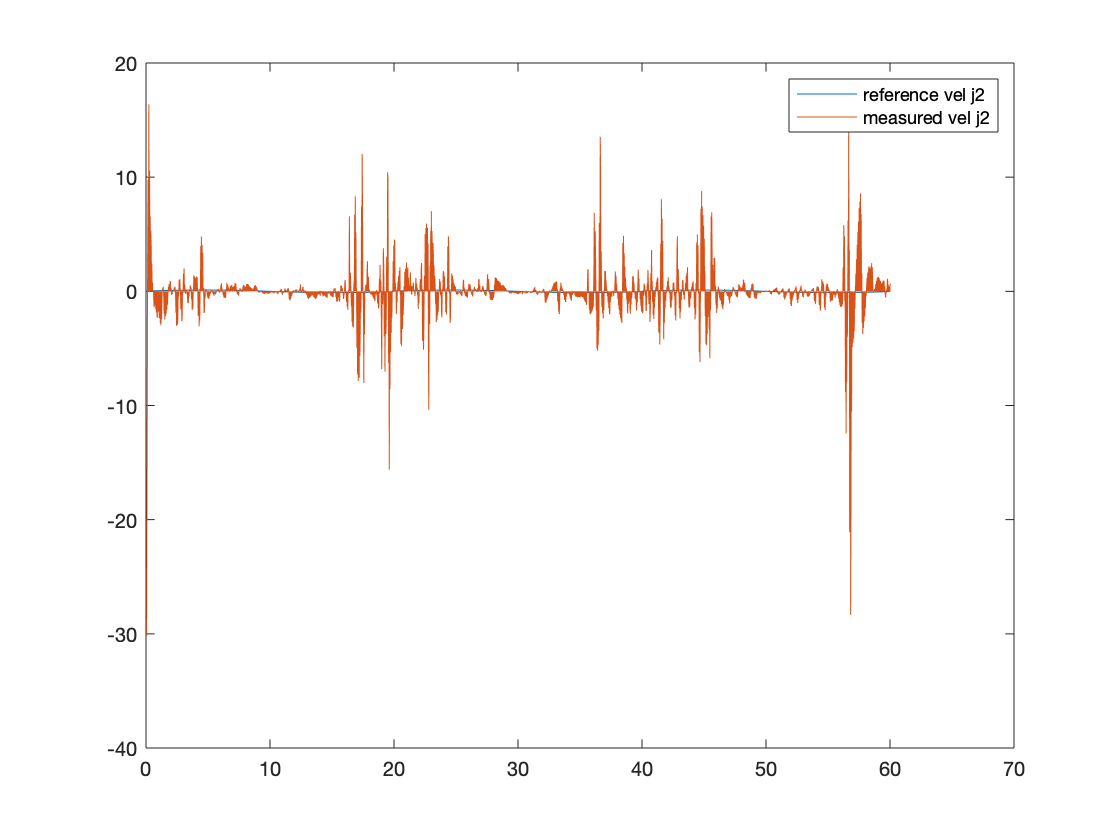

clf;
plot(time_axis(1, 1:i-1), reference_vel(2, 1:i-1), time_axis(1, 1:i-1), measured_vel(2, 1:i-1));
legend ("reference vel j2", "measured vel j2")

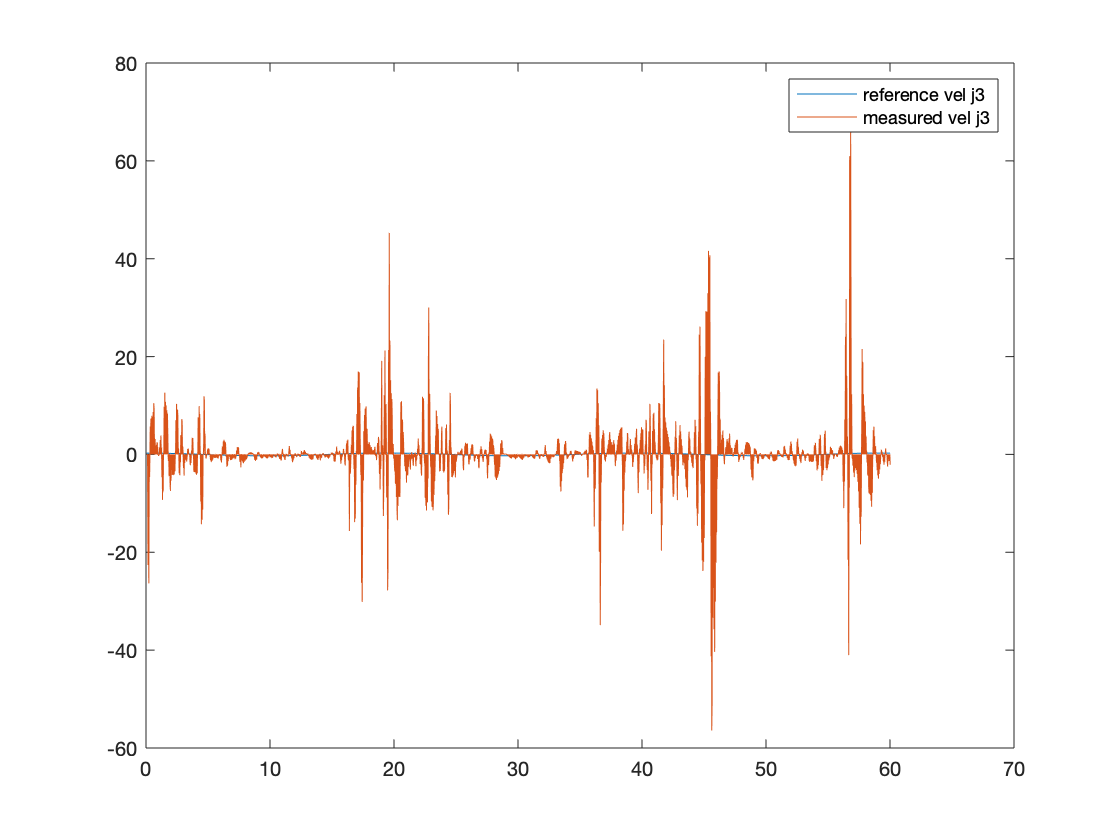

clf;
plot(time_axis(1, 1:i-1), reference_vel(3, 1:i-1), time_axis(1, 1:i-1), measured_vel(3, 1:i-1));
legend ("reference vel j3", "measured vel j3")

% clf
% plot(time_axis(1, 1:i-1), derror(1, 1:i-1));
% legend("velocity error")

% clf
% plot(time_axis(1, 1:i-1), ierror(1, 1:i-1));
% legend("integral error")

filtered_vel = zeros(3, i-1);

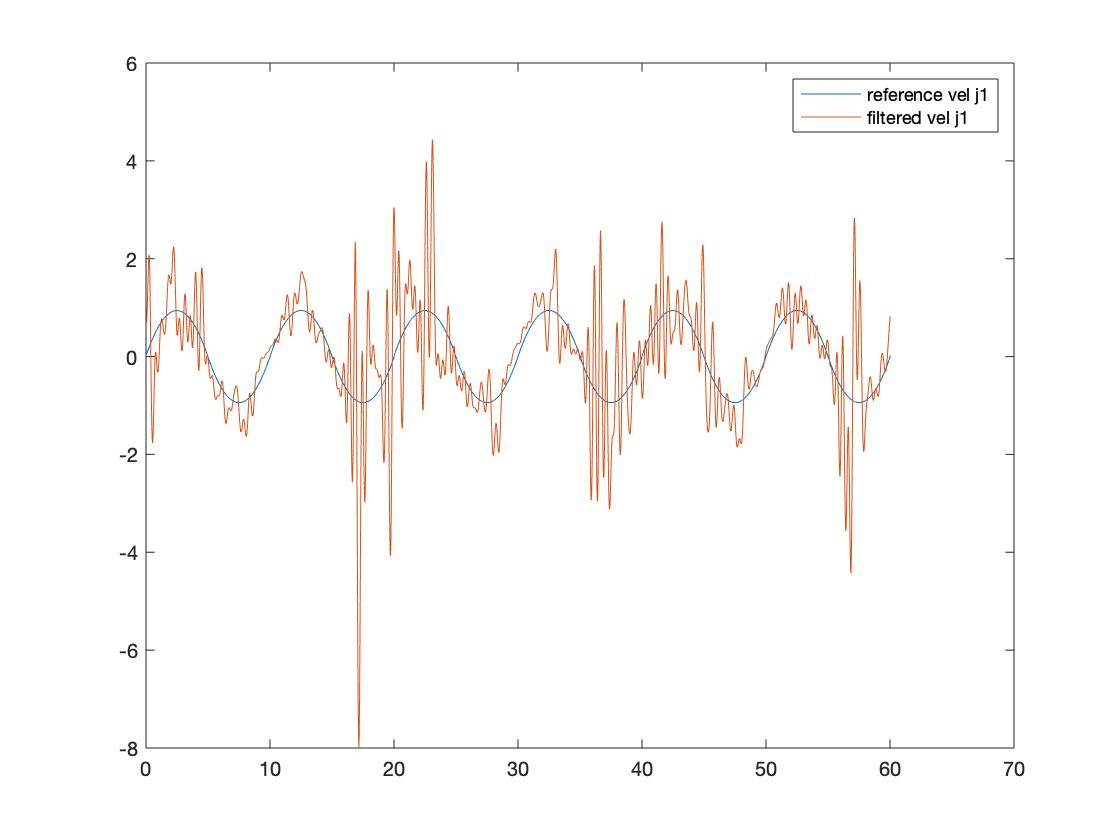

filtered_vel(1, :) = filtfilt(filt, gradient(measured_pos(1, 1:i-1),frame_period));
plot(time_axis(1, 1:i-1), reference_vel(1, 1:i-1), time_axis(1, 1:i-1), filtered_vel(1, 1:i-1));
legend ("reference vel j1", "filtered vel j1")

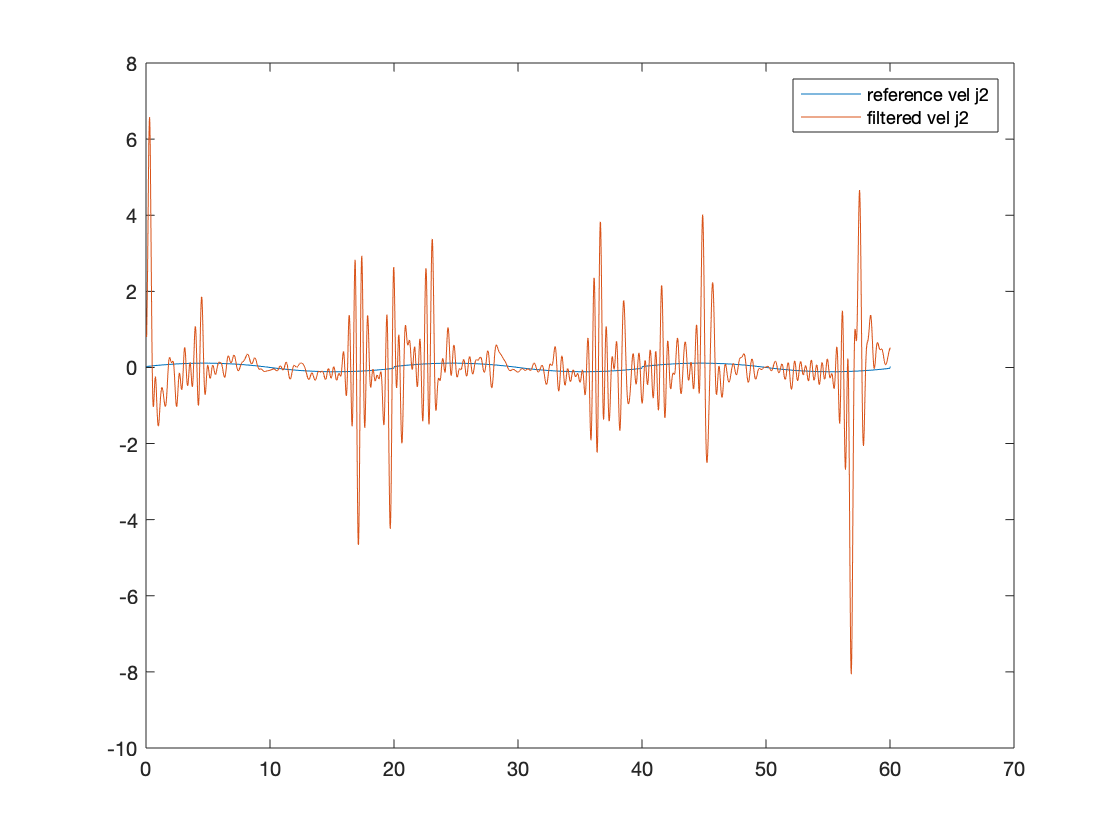

filtered_vel(2, :) = filtfilt(filt, gradient(measured_pos(2, 1:i-1),frame_period));
plot(time_axis(1, 1:i-1), reference_vel(2, 1:i-1), time_axis(1, 1:i-1), filtered_vel(2, 1:i-1));
legend ("reference vel j2", "filtered vel j2")

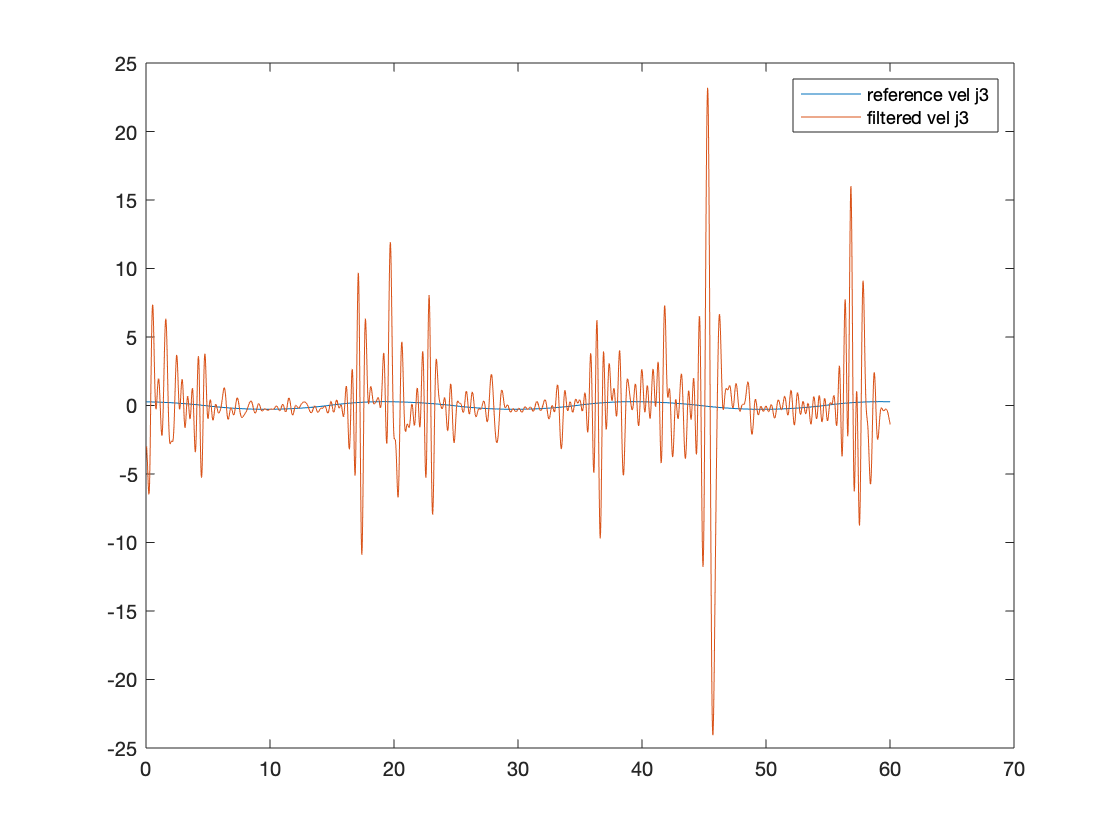

filtered_vel(3, :) = filtfilt(filt, gradient(measured_pos(3, 1:i-1),frame_period));
plot(time_axis(1, 1:i-1), reference_vel(3, 1:i-1), time_axis(1, 1:i-1), filtered_vel(3, 1:i-1));
legend ("reference vel j3", "filtered vel j3")

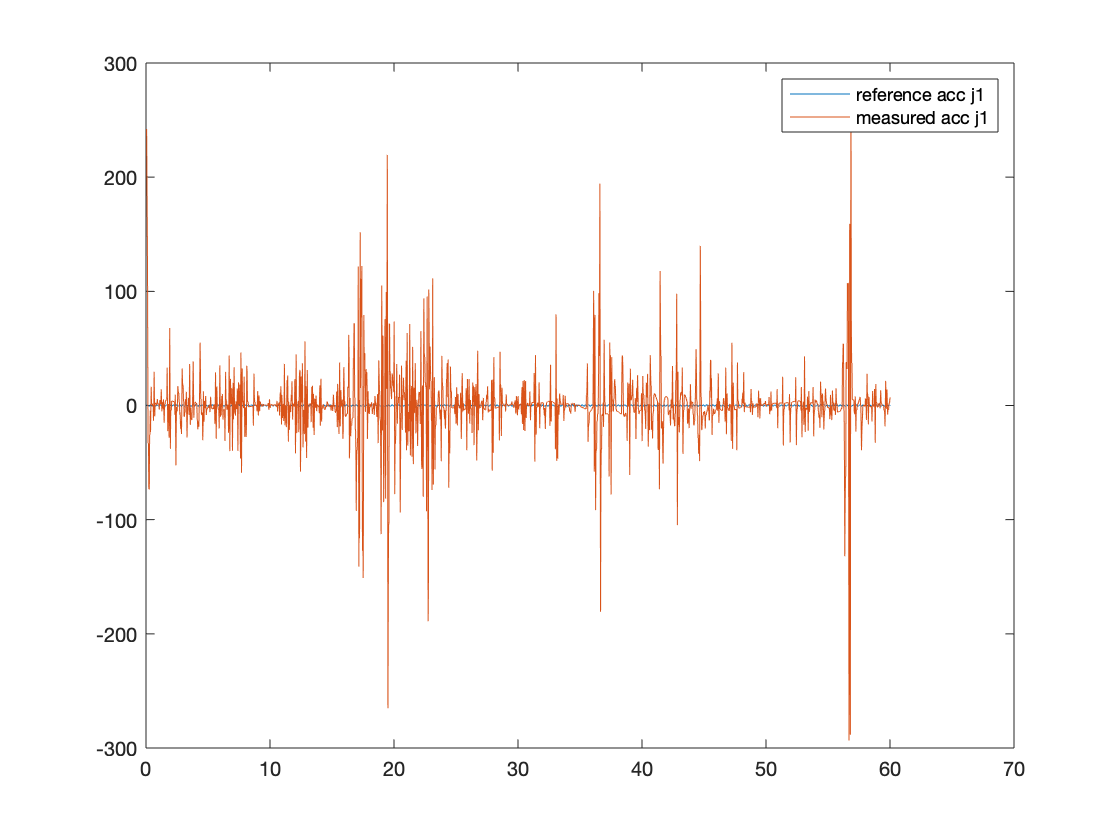

clf;
plot(time_axis(1, 1:i-1), acceleration{1}(1:i-1), time_axis(1, 1:i-1), gradient(gradient(measured_pos(1, 1:i-1), frame_period), frame_period));
legend ("reference acc j1", "measured acc j1")

filtered_acc = zeros(3, i-1);

filtered_acc(1, :) = filtfilt(filt,gradient(filtfilt(filt,gradient(measured_pos(1, 1:i-1), frame_period)), frame_period));
filtered_acc(2, :) = filtfilt(filt,gradient(filtfilt(filt,gradient(measured_pos(2, 1:i-1), frame_period)), frame_period));
filtered_acc(3, :) = filtfilt(filt,gradient(filtfilt(filt,gradient(measured_pos(3, 1:i-1), frame_period)), frame_period));

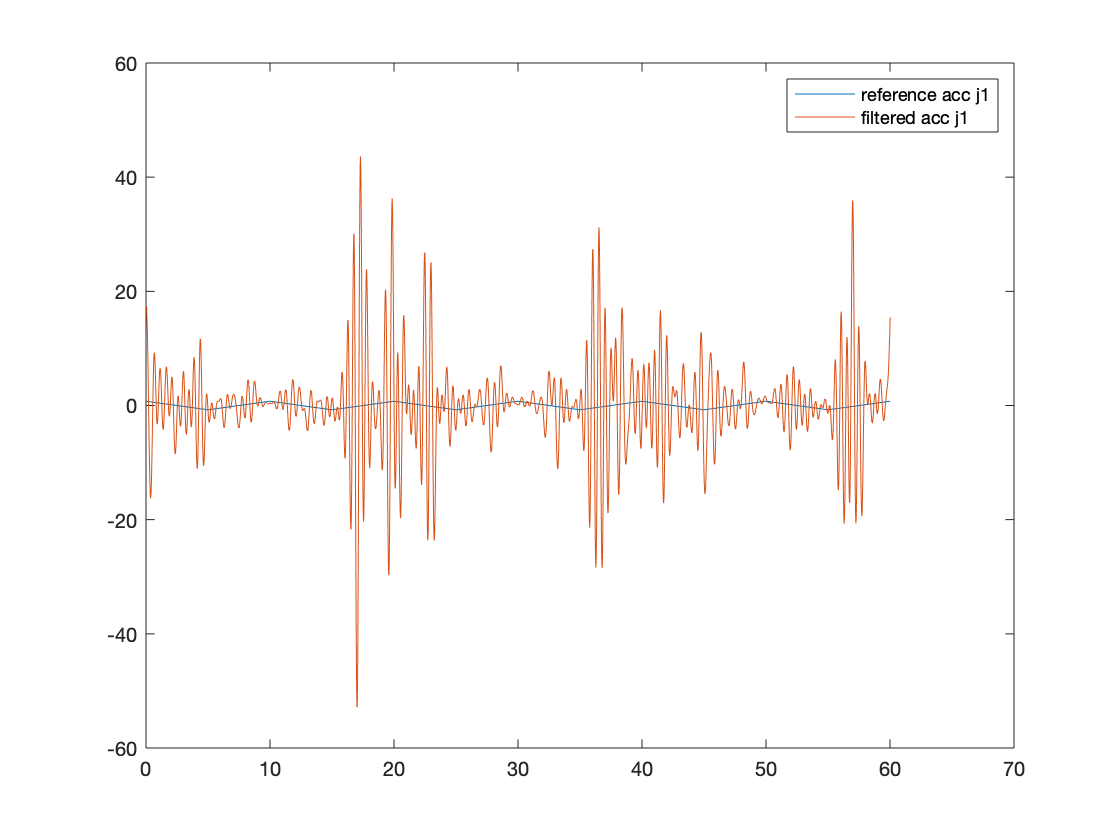

plot(time_axis(1, 1:i-1), acceleration{1}(time_axis(1, 1:i-1)), time_axis(1, 1:i-1), filtered_acc(1, 1:i-1));
legend ("reference acc j1", "filtered acc j1")

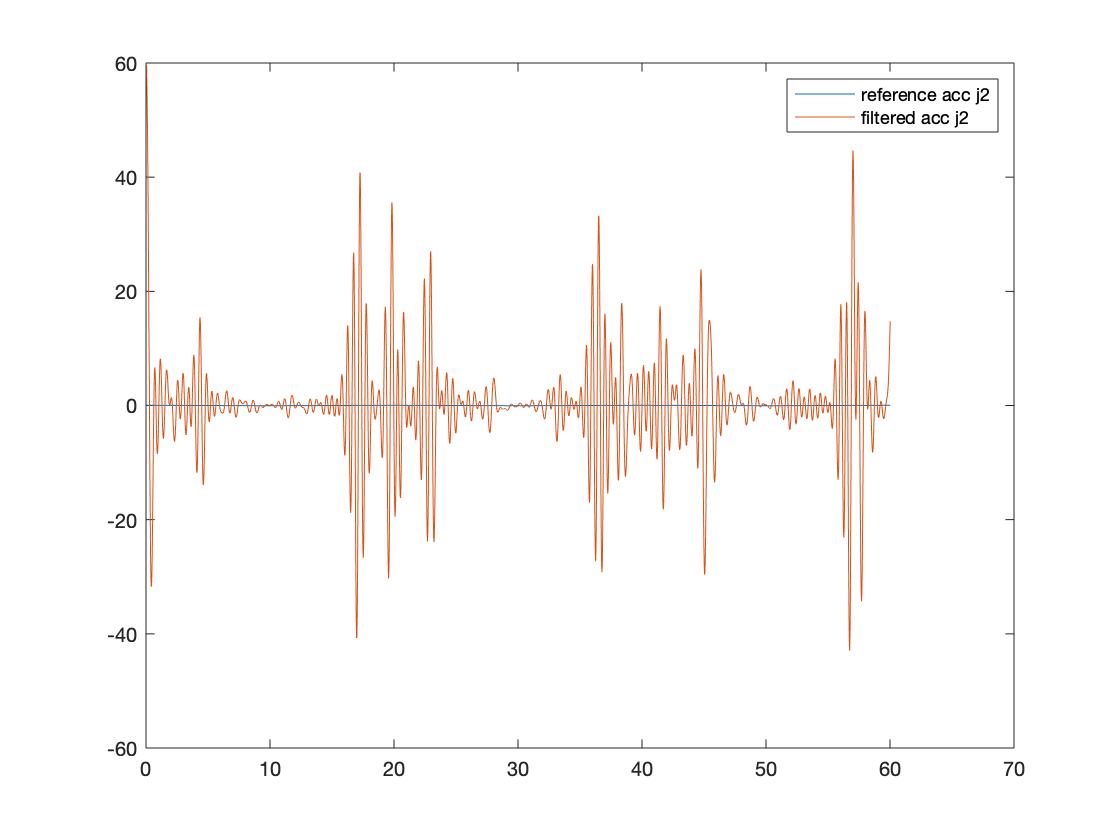

plot(time_axis(1, 1:i-1), acceleration{2}(time_axis(1, 1:i-1)), time_axis(1, 1:i-1), filtered_acc(2, 1:i-1));
legend ("reference acc j2", "filtered acc j2")

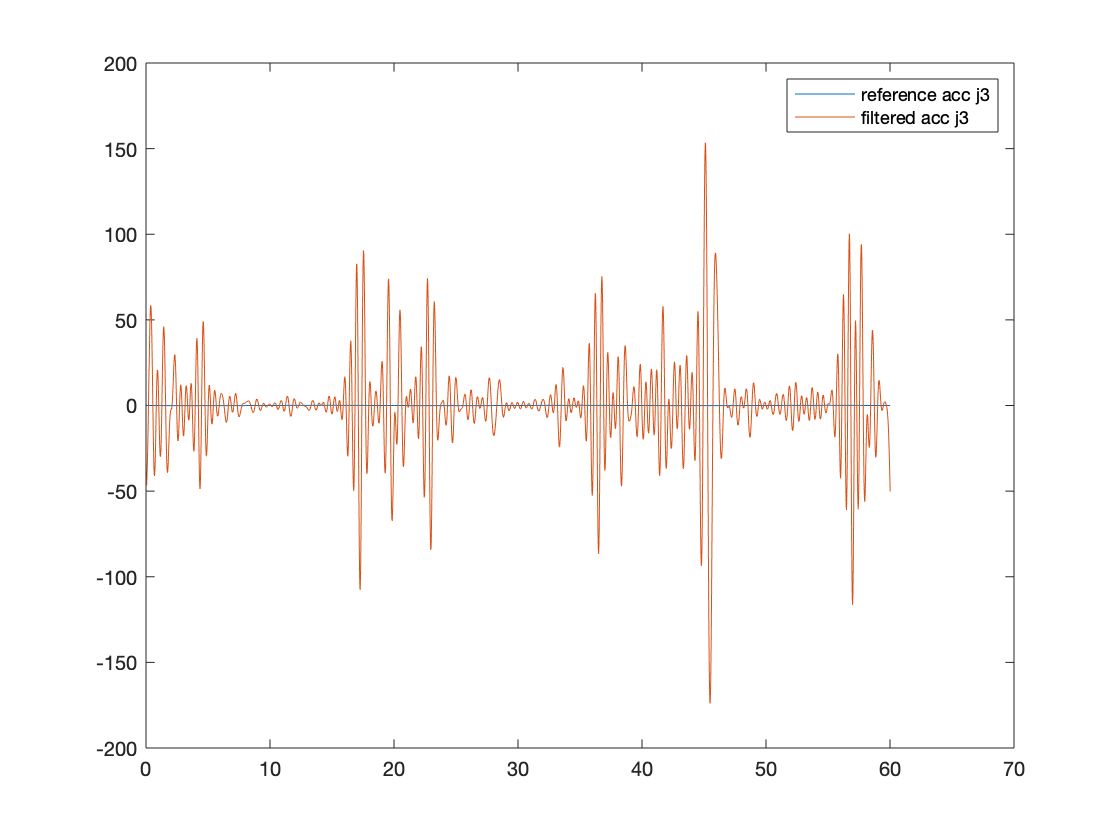

plot(time_axis(1, 1:i-1), acceleration{3}(time_axis(1, 1:i-1)), time_axis(1, 1:i-1), filtered_acc(3, 1:i-1));
legend ("reference acc j3", "filtered acc j3")

filtered_torque = zeros(3, i-1);

filtered_torque(1, :) = filtfilt(filt, torque(1, 1:i-1));
filtered_torque(2, :) = filtfilt(filt, torque(2, 1:i-1));
filtered_torque(3, :) = filtfilt(filt, torque(3, 1:i-1));

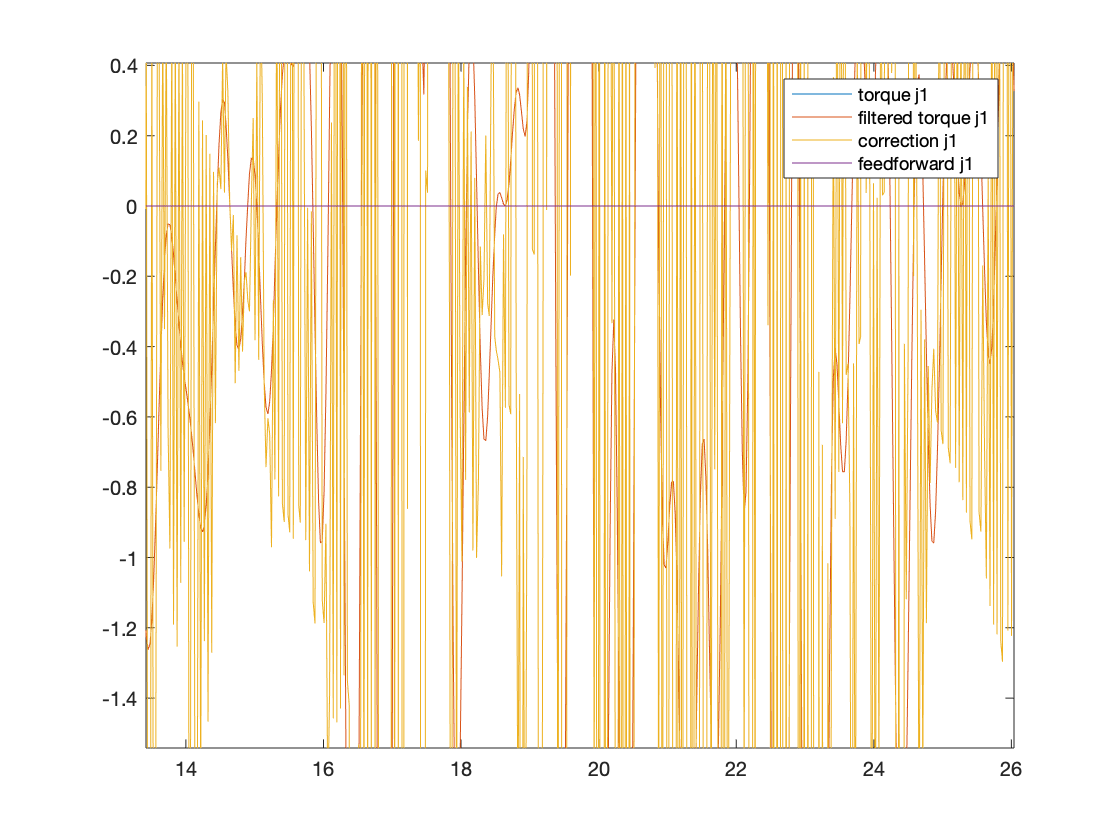

plot(time_axis(1, 1:i-1), torque(1, 1:i-1), time_axis(1, 1:i-1), filtered_torque(1, 1:i-1), time_axis(1, 1:i-1), correction(1, 1:i-1), time_axis(1, 1:i-1), computed(1, 1:i-1));
legend ("torque j1", "filtered torque j1", "correction j1", "feedforward j1")

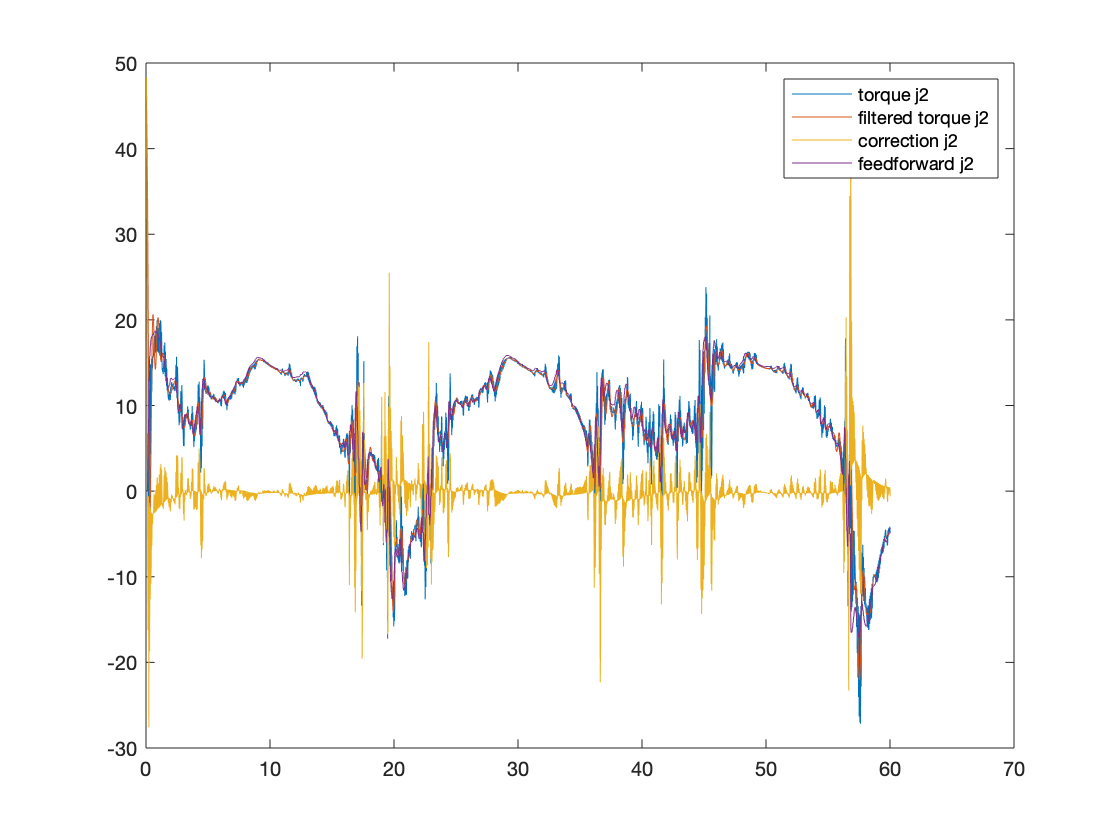

plot(time_axis(1, 1:i-1), torque(2, 1:i-1), time_axis(1, 1:i-1), filtered_torque(2, 1:i-1), time_axis(1, 1:i-1), correction(2, 1:i-1), time_axis(1, 1:i-1), computed(2, 1:i-1));
legend ("torque j2", "filtered torque j2", "correction j2", "feedforward j2")

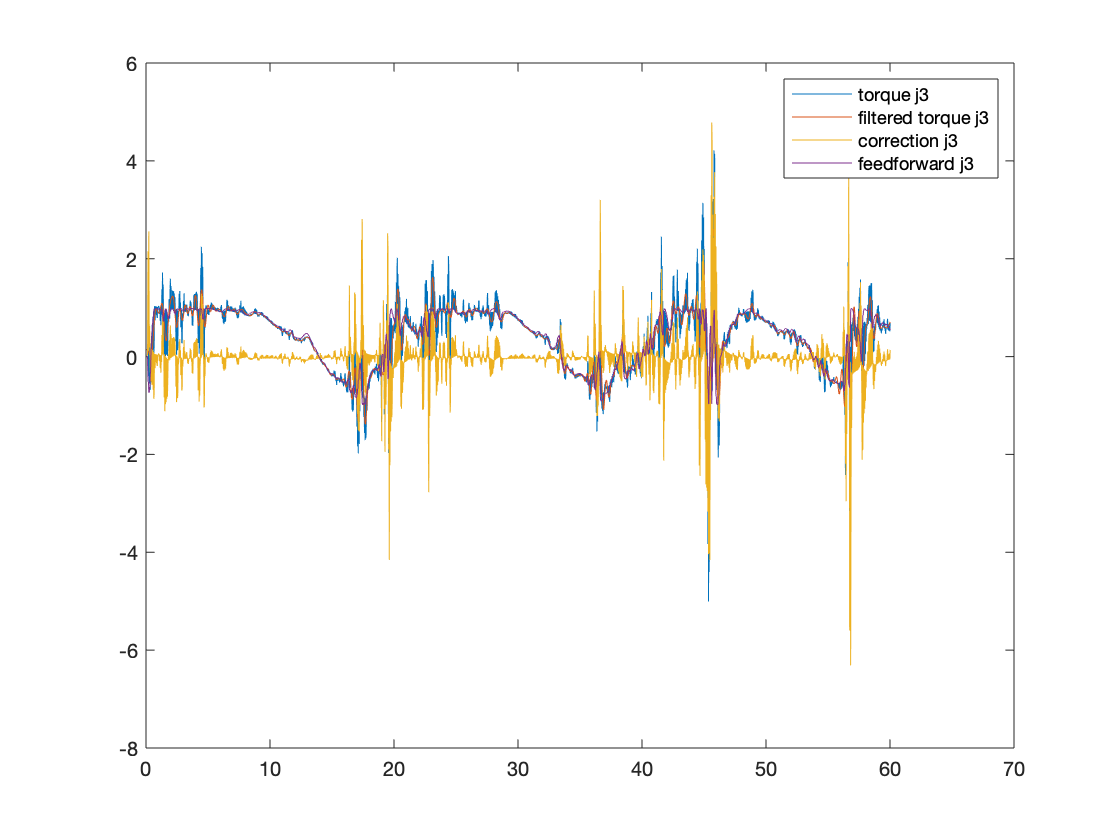

plot(time_axis(1, 1:i-1), torque(3, 1:i-1), time_axis(1, 1:i-1), filtered_torque(3, 1:i-1), time_axis(1, 1:i-1), correction(3, 1:i-1), time_axis(1, 1:i-1), computed(3, 1:i-1));
legend ("torque j3", "filtered torque j3", "correction j3", "feedforward j3")

Y_stack = zeros((i-1)*3,13)

Y_stack =      0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


u_stack = zeros((i-1)*3,1)

u_stack =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for k=1:(i-1)
    Y_stack(k*3-2:k*3,:) = Y_matrix(measured_pos(1,k),measured_pos(2,k),measured_pos(3,k),filtered_vel(1,k),filtered_vel(2,k),filtered_vel(3,k),filtered_acc(1,k),filtered_acc(2,k),filtered_acc(3,k));
    u_stack(k*3-2:k*3,:) = filtered_torque(:,k);
end

save('data/3-dof/experiment1/Y_stack.mat', 'Y_stack');
save('data/3-dof/experiment1/u_stack.mat', 'u_stack');

% p = [200*rand(), 0, 0.3*rand(), 0, 0.08*rand(),20*rand(),0.3*rand(),0,0.1*rand(),0.008*rand(),0.15*rand(),0.15*rand(),2*rand(),0.2*rand(),0,0,0.0008*rand(),0.01*rand(),0.01*rand()];

%algorithm

% epsilon = 0
% for i=1:1
%     m1 = optimvar('m1');
%     m2 = optimvar('m2');
%     m3 = optimvar('m3');
%     rc1x = optimvar('rc1x');
%     rc1y = optimvar('rc1y');
%     rc1z = optimvar('rc1z');
%     rc2x = optimvar('rc2x');
%     rc2y = optimvar('rc2y');
%     rc2z = optimvar('rc2z');
%     rc3x = optimvar('rc3x');
%     rc3y = optimvar('rc3y');
%     rc3z = optimvar('rc3z');
%     I1yy = optimvar('I1yy');
%     I2xx = optimvar('I2xx');
%     I2yy = optimvar('I2yy');
%     I2zz = optimvar('I2zz');
%     I3xx = optimvar('I3xx');
%     I3yy = optimvar('I3yy');
%     I3zz = optimvar('I3zz');
%   
%     prob = optimproblem;
%     prob.Objective = sum((Y_stack*dinamic_coefficients(m1,rc1x,rc1y,rc1z,I1yy,m2,rc2x,rc2y,rc2z,I2xx,I2yy,I2zz,m3,rc3x,rc3y,rc3z,I3xx,I3yy,I3zz)-u_stack).^2);
%     
%     prob.Constraints.cons1 = m1 >= 0;
%     prob.Constraints.cons2 = m2 >= 0;
%     prob.Constraints.cons3 = m3 >= 0;
%     prob.Constraints.cons4 = m1+m2+m3 >= 111;
%     prob.Constraints.cons5 = m1+m2+m3 <= 111;
%     prob.Constraints.cons6 = rc1x >= 0;
%     prob.Constraints.cons7 = rc1x <= 0;
%     prob.Constraints.cons8 = rc1y >= 0;
%     prob.Constraints.cons9 = rc1y <= 0.3;
%     prob.Constraints.cons10 = rc1z >= 0;
%     prob.Constraints.cons11 = rc1z <= 0;
%     prob.Constraints.cons12 = rc2x >= 0;
%     prob.Constraints.cons13 = rc2x <= 0.3;
%     prob.Constraints.cons14 = rc2y >= 0;
%     prob.Constraints.cons15 = rc2y <= 0;
%     prob.Constraints.cons16 = rc2z >= 0;
%     prob.Constraints.cons17 = rc2z <= 0.1;
%     prob.Constraints.cons18 = rc3x >= 0;
%     prob.Constraints.cons19 = rc3x <= 0.2;
%     prob.Constraints.cons20 = rc3y >= 0;
%     prob.Constraints.cons21 = rc3y <= 0;
%     prob.Constraints.cons22 = rc3z >= 0;
%     prob.Constraints.cons23 = rc3z <= 0;
%     prob.Constraints.cons24 = I1yy >=0;
%     prob.Constraints.cons25 = I2xx >=0;
%     prob.Constraints.cons26 = I2yy >=0;
%     prob.Constraints.cons27 = I2zz >=0;
%     prob.Constraints.cons28 = I3xx >=0;
%     prob.Constraints.cons29 = I3yy >=0;
%     prob.Constraints.cons30 = I3zz >=0;
%     prob.Constraints.cons31 = I2xx+I2yy >= I2zz;
%     prob.Constraints.cons32 = I2zz+I2yy >= I2xx;
%     prob.Constraints.cons33 = I2xx+I2zz >= I2yy;
%     prob.Constraints.cons34 = I3xx+I3yy >= I3zz;
%     prob.Constraints.cons35 = I3zz+I3yy >= I3xx;
%     prob.Constraints.cons36 = I3xx+I3zz >= I3yy;
% 
%     x0.m1 = p(1);
%     x0.rc1x = p(2);
%     x0.rc1y = p(3);
%     x0.rc1z = p(4);
%     x0.I1yy = p(5);
%     x0.m2 = p(6);
%     x0.rc2x = p(7);
%     x0.rc2y = p(8);
%     x0.rc2z = p(9);
%     x0.I2xx = p(10);
%     x0.I2yy = p(11);
%     x0.I2zz = p(12);
%     x0.m3 = p(13);
%     x0.rc3x = p(14);
%     x0.rc3y = p(15);
%     x0.rc3z = p(16);
%     x0.I3xx = p(17);
%     x0.I3yy = p(18);
%     x0.I3zz = p(19);
%     
%     sol = solve(prob, x0)
% end